# Speech-To-Text Transcription Using wav2vec 2.0

This example provides a pretrained wav2vec 2.0 model [2]. The wav2vec model is a multi-headed transformer-based neural network that achieves state-of-the-art speech-to-text transcription. The model uses semi-supervised training--meaning that it is first trained on a large set of unlabeled speech using contrastive loss and then trained on a smaller labeled dataset. This enables the model to be tuned to different downstream tasks such as emotion detection, speaker recognition, and language detection. Also, the semi-supervised training approach means the model can be trained for languages that do not have large, labeled datasets available. 

The wav2vec 2.0 inference model provided in this example uses the base model with a 960 hour finetuning split. The wav2vec 2.0 inference path consists of a feature encoder, a positional encoder, a context network, and a decoder. You can step through the supporting functions to examine the structure of each module.

## Perform Speech-to-Text

Load an audio file and listen to it.

mlock % Lock memory to prevent clearing and reloading model.
file = "002.flac";
[speech,fs] = audioread(file);

sound(speech,fs)

The supporting function `wav2vec` loads the baseline 960 hours weights and accompanying architecture and then passes the input `x` through the model. Call `wav2vec` with the raw waveform and sample rate.

trans = wav2vec(speech,fs)

trans = "THE MAN NO LONGER PRODUCED ON HER THE EFFECT OF BEING OLD OR POOR SHE THOUGHT JEAN VALJEAN HANDSOME JUST AS SHE THOUGHT THE HOVEL PRETTY"

munlock % Unlock memory

# Supporting Functions

### wav2vec 2.0

wav2vec 2.0 is a framework for self-supervised learning of speech representations [2].

function txt = wav2vec(X,fs)
%WAV2VEC Speech-to-text transcription
% txt = wav2vec(x,fs) performs speech-to-text transcription on the audio
% signal x with sample rate fs. The output txt is a string. The function
% uses the pretrained baseline 960 hrs system with the corresponding
% wave2vec 2.0 architecture.
persistent featureEncoder Learnables Dictionary
if isempty(Learnables) || isempty(featureEncoder) || isempty(Dictionary)
    loc = matlab.internal.examples.downloadSupportFile('audio','wav2vec2/wav2vec2-base-960.zip');
    unzip(loc,pwd)
    load("wav2vec2-base-960.mat","Learnables","Dictionary")
    if canUseGPU()
        Learnables = dlupdate(@(x)gpuArray(x),Learnables);
    end
    featureEncoder = constructFeatureEncoder(Learnables.featureEncoder);
end

% Normalize and resample if necessary
X = wav2vecPreprocess(X,fs);

% Feature encoding
X = squeeze(stripdims(featureEncoder.forward(X)));

% Positional encoding
X = positionalEncoder(X,Learnables.positionalEncoder);

% Transformer encoding
X = transformerEncoder(X,Learnables.transformerEncoder);

% Text decoding
txt = textDecoder(X,Dictionary);

end


### Preprocess Audio

Preprocessing for the wav2vec network consists of normalizing the audio and, if necessary, converting to mono and resampling to 16 kHz.

function y = wav2vecPreprocess(x,fs)
%WAV2VECPREPROCESS Preprocess audio for wav2vec model
% y = wav2vecPreprocess(x,fs) applies preprocessing to the audio input x with
% sampling rate fs and returns the preprocessed signal y.

% If Parallel Computing Toolbox(TM) is installed and licensed and a
% supported GPU and driver are present, then convert signal to gpuArray.
if canUseGPU()
    x = gpuArray(x);
end

% Convert to mono if required
x = mean(x,2);

% Resample to 16 kHz if required
desiredFs = 16e3;
if fs ~= desiredFs
    x = resample(x,desiredFs,fs);
end

% Normalize audio
offset = 1e-5;
y = (x - mean(x)) / sqrt(var(x) + offset);

% Convert signal to dlarray
y = dlarray(y,"TCB");

end

### Feature Encoding

The feature encoder passes raw audio input through seven 1-D convolutional blocks. The first block includes an instance (channel-wise) normalization layer between the convolution and GELU activation layers. The output of the convolutional blocks is passed through layer normalization. The total context of the encoder receptive field is 400 samples which corresponds to 25 ms at the 16 kHz input sample rate.

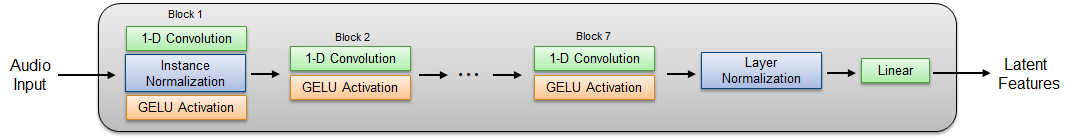

function net = constructFeatureEncoder(params)
%CONSTRUCTFEATUREENCODER Construct feature encoder
% net = constructFeatureEncoder(params) returns a dlnetwork consisting of 7
% 1-D convoluational blocks for feature encoding.
layers = [
    sequenceInputLayer(1,MinLength=400,Name="input")

    convolution1dLayer(10,512,Stride=5,Weights=params.conv1d_1.Weights,Name="conv1d_1")
    instanceNormalizationLayer(Scale=params.instancenorm_1.Scale,Offset=params.instancenorm_1.Offset,Name="instancenorm_1")
    customLayer.geluLayer(Name="gelu_1")

    convolution1dLayer(3,512,Stride=2,Weights=params.conv1d_2.Weights,Name="conv1d_2")
    customLayer.geluLayer(Name="gelu_2")

    convolution1dLayer(3,512,Stride=2,Weights=params.conv1d_3.Weights,Name="conv1d_3")
    customLayer.geluLayer(Name="gelu_3")

    convolution1dLayer(3,512,Stride=2,Weights=params.conv1d_4.Weights,Name="conv1d_4")
    customLayer.geluLayer(Name="gelu_4")

    convolution1dLayer(3,512,Stride=2,Weights=params.conv1d_5.Weights,Name="conv1d_5")
    customLayer.geluLayer(Name="gelu_5")

    convolution1dLayer(2,512,Stride=2,Weights=params.conv1d_6.Weights,Name="conv1d_6")
    customLayer.geluLayer(Name="gelu_6")

    convolution1dLayer(2,512,Stride=2,Weights=params.conv1d_7.Weights,Name="conv1d_7")
    customLayer.geluLayer(Name="gelu_7")

    layerNormalizationLayer(Offset=params.layernorm_1.Offset,Scale=params.layernorm_1.Scale,Name="layernorm_1")

    fullyConnectedLayer(768,Weights=params.fc_1.Weights,Bias=params.fc_1.Bias,Name="fc_1")
    ];

b = layerGraph(layers);
net = dlnetwork(b);
end

### Positional Encoding

The positional encoder passes the latent features through grouped 1-D convolution to create a relative positional vector which is then added to the latent features to encode the position of the features relative to one another.

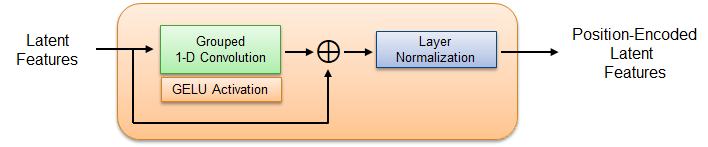

function X = positionalEncoder(X,params)
%POSITIONALENCODER Positional encoding
% dlY = positionalEncoder(Y,params) encodes Y with a relative
% positional encoding vector then applies layer normalization.

% 1-D convolution layer
Xe = positionalEmbedding(X,params.positionalEmbedding);

% Residual connection and normalization
X = Xe + X;
X = layernorm(X,params.layernorm.offset,params.layernorm.scaleFactor,DataFormat="CB");

    function z = positionalEmbedding(x,params)
        %POSITIONALEMBEDDING Positional embedding
        % z = positionalEmbedding(x,params) performs grouped 1-d
        % convolution and returns a relative positional embedding vector
        % described in [1].

        % 1-D convolution
        z = dlconv(x,params.Weights,params.Bias,DataFormat="CTB",WeightsFormat="TUCU",Stride=1,Padding=64);
        z = z(:,1:end-1);

        % GELU activation
        z = gelu(z);
    end
end

### Transformer Encoding

The context network applies twelve encoder blocks in sequence. Each block applies multi-head attention and feed forward blocks in sequence. The feedforward block consists of two fully-connected layers separated by a GELU layer.

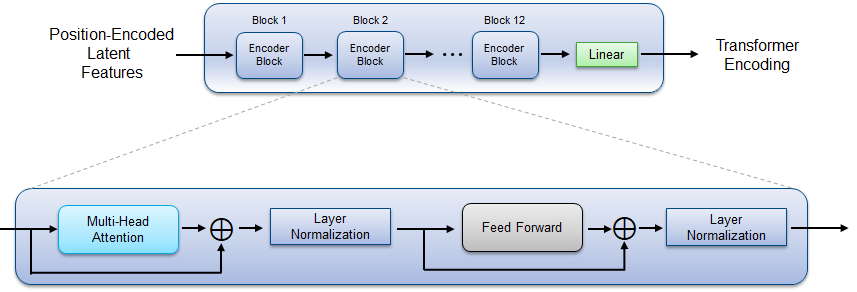

function Y = transformerEncoder(X,params)
%TRANSFORMERENCODER Transformer encoding
% Y = transformerEncoder(X,params) passes X through 12 encoder blocks
% in sequence then applies a fully-connected layer.

X = encoderBlock(X,params.block_1);
X = encoderBlock(X,params.block_2);
X = encoderBlock(X,params.block_3);
X = encoderBlock(X,params.block_4);
X = encoderBlock(X,params.block_5);
X = encoderBlock(X,params.block_6);
X = encoderBlock(X,params.block_7);
X = encoderBlock(X,params.block_8);
X = encoderBlock(X,params.block_9);
X = encoderBlock(X,params.block_10);
X = encoderBlock(X,params.block_11);
X = encoderBlock(X,params.block_12);

Y = fullyconnect(X,params.fc.Weights,params.fc.Bias,DataFormat="CB");

    function X = encoderBlock(X,params)
        %ENCODERBLOCK Encoder block
        % X = encoderBlock(X,params) passes Y through an encoder
        % block.
        %
        % See section 3.1 of [1].

        % Multi-Head Attention
        xa = multiheadAttention(X',params.multiheadAttention);

        % Add & Norm
        X = X + xa;
        X = layernorm(X,params.layernorm_1.offset,params.layernorm_1.scaleFactor,DataFormat="CB");

        % Feed Forward
        xff = fullyconnect(X,params.fc_1.Weights,params.fc_1.Bias,DataFormat="CB");
        xff = gelu(xff);
        xff = fullyconnect(xff,params.fc_2.Weights,params.fc_2.Bias,DataFormat="CB");

        % Add & Norm
        X = X + xff;
        X = layernorm(X,params.layernorm_2.offset,params.layernorm_2.scaleFactor,DataFormat="CB");

    end
end

#### Multi-Head Attention

Each block of the context network has three linear (fully-connected) layers which output the Q (query), K (key), and V (value) vectors. The Q, K, and V vectors are then chunked into twelve (the number of heads in the system) non-overlapping sections. Scaled dot-product attention is applied to each chunk individually and the results are concatenated. The output is passed through a linear layer to form multi-head attention.

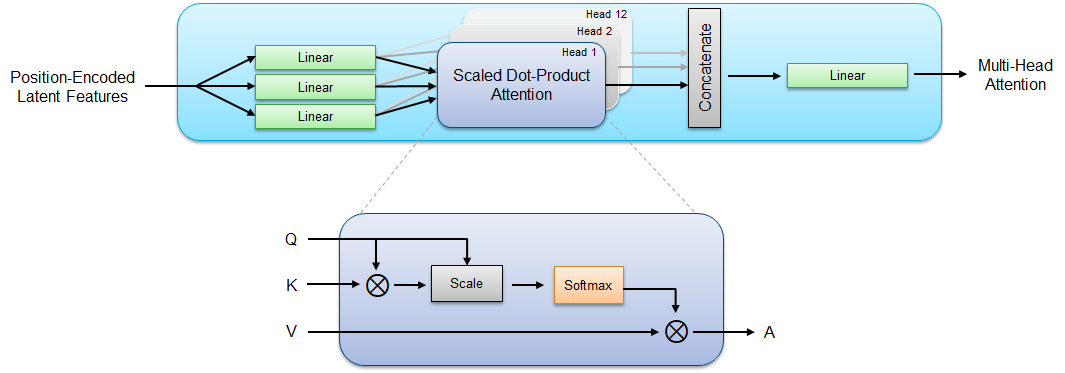

function A = multiheadAttention(X,params)
%MULTIHEADATTENTION Multi-head attention
% A = multiheadAttention(X,params) performs multi-head attention
% described in section 3.2.2 of [1].

numHeads = 12;

% Linear
K = fullyconnect(X,params.fc_1.Weights,params.fc_1.Bias,DataFormat="BC");
V = fullyconnect(X,params.fc_2.Weights,params.fc_2.Bias,DataFormat="BC");
Q = fullyconnect(X,params.fc_3.Weights,params.fc_3.Bias,DataFormat="BC");

% Scaled dot-product attention
A = scaledDotProductAttention(Q,K,V,numHeads);

% Concatenation
A = iMergeHeads(A);

% Linear
A = fullyconnect(A,params.fc_4.Weights,params.fc_4.Bias,DataFormat="CB");

    function A = scaledDotProductAttention(Q,K,V,numHeads)
        %SCALEDDOTPRODUCTATTENTION Scaled dot-product attention
        % A = scaledDotProductAttention(Q,K,V,numHeads)
        % performs scaled dot-product attention described in section 3.2.1 of [1].

        % The function is vectorized to apply attention to all heads
        % simultaneously.

        numFeatures = size(K,1);

        % Matrix multiplication
        K = iSplitHeadsQ(K,numFeatures,numHeads);
        Q = iSplitHeads(Q,numFeatures,numHeads);
        W = dlmtimes(K,Q);

        % Scale
        W = W./sqrt(size(Q,1));

        % Softmax
        W = softmax(W,DataFormat="CTUB");

        % Matrix multiplication
        V = iSplitHeads(V,numFeatures,numHeads);
        A = dlmtimes(V,W);

        function Z = iSplitHeads(X,numFeatures,numHeads)
            % For the key and value vectors, permute to put the dimension for
            % the heads last and the sequence length second. This enables
            % batched matrix multiplication to compute attention for all of the
            % heads at once.
            X = reshape(X,numFeatures/numHeads,numHeads,[],1);
            Z = permute(X,[1,3,2]);
        end
        function Z = iSplitHeadsQ(X,numFeatures,numHeads)
            % For the query vector, permute to put the dimension of the heads
            % last and the sequence length first. This enables batched matrix
            % multiplication to compute attention for all of the heads at once.
            X = reshape(X,numFeatures/numHeads,numHeads,[],1);
            Z = permute(X,[3,1,2]);
        end
    end
    function Z = iMergeHeads(X)
        % Merge the numFeatures-by-sequenceLength-by-numHeads array to a
        % (numFeatures*numHeads)-by-sequenceLength array
        X = permute(X,[1,3,2]);
        Z = reshape(X,size(X,1)*size(X,2),[]);
    end

end

### Text Decoding

Use a greedy decoding algorithm to sample the most probable tokens at each time step. Since the model is trained using connectionist temporal classification (CTC), post-procesing is required to remove duplicated blank tokens. This is the simplest decoding method and includes a minimalist language model.

function txt = textDecoder(Y,dict)
%TEXTDECODER Text decoding
% txt = textDecoder(y,dict) decodes wav2vec 2.0 output y to text txt
% using the map in dict.

txt = '';
for ii = 1:size(Y,2)
    [~,argmax] = max(Y(:,ii));
    if ~endsWith(txt,dict{argmax})
        txt = txt + dict{argmax};
    end
end

txt = replace(txt,'<pad>','');
txt = replace(txt,'|',' ');
txt = char(txt);
if ~isempty(txt) && txt(end)==' '
    txt = txt(1:end-1);
end
txt = string(txt);

end

### Gaussian Error Linear Unit (GELU) Activation

function Z = gelu(x)
%GELU Apply GELU activation
% Z = gelu(x) applies Gaussian error linear unit (GELU) activation to the
% input x.

Z = 0.5*x.*(1 + tanh(sqrt(2/pi)*(x + 0.044715*(x.^3))));

end

# References

[1] Ashish Vaswani, Noam Shazeer, Niki Parmar, Jakob Uszkoreit, Llio Jones, Aidan N. Gomez, Lukasz Kaiser, Illia Polosukhin, "Attention Is All You Need", https://arxiv.org/abs/1706.03762

[2] Alexei Baevski, Henry Zhou, Abdelrahman Mohamed, and Michael Auli. wav2vec 2.0: A framework for self-supervised learning of speech representations. arXiv preprint arXiv:2006.11477, 2020.

[3] J. L. Ba, J. R. Kiros, and G. E. Hinton. Layer normalization. arXiv, 2016

[4] A. Baevski, M. Auli, and A. Mohamed. Effectiveness of self-supervised pre-training for speech recognition. arXiv, abs/1911.03912, 2019.

[5] A. Baevski, S. Schneider, and M. Auli. vq-wav2vec: Self-supervised learning of discrete speech representations. In Proc. of ICLR, 2020.

[6] T. Chen, S. Kornblith, M. Norouzi, and G. Hinton. A simple framework for contrastive learning of visual representations. arXiv, abs/2002.05709, 2020.

*Copyright 2021 The MathWorks, Inc.*